map = load("multilayerMap.mat").map;

binaryMap = map(:,:,1);
speedMap = map(:,:,2);
trafficMap = map(:,:,3);
obstacleMap = map(:,:,4);

Binary Map Display

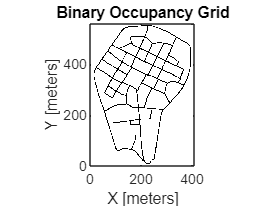

binaryOccMap = binaryOccupancyMap(binaryMap);
show(binaryOccMap)

Speed Limit Cost Map

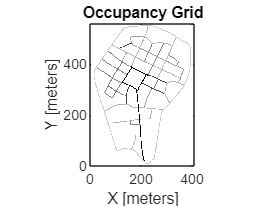

costMap_normalized = speedMap./max(max(speedMap));
speedOccMap = occupancyMap(costMap_normalized);

show(speedOccMap)

Traffic Intensity

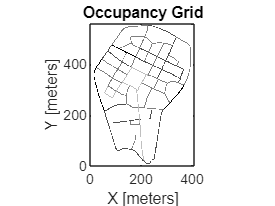

trafficMap_normalized = trafficMap./max(max(trafficMap));
trafficOccMap = occupancyMap(trafficMap_normalized);

show(trafficOccMap)

Obstacle Map

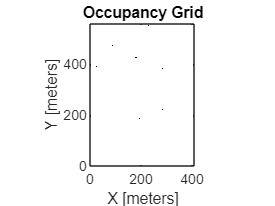

obstacleMap_normalized = obstacleMap./max(max(obstacleMap));
obstacleOccMap = occupancyMap(obstacleMap_normalized);

show(obstacleOccMap)

Full Cost Map

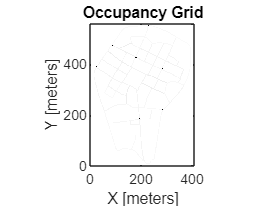

cost = speedMap .* trafficMap + obstacleMap;

costMap_normalized = cost./max(max(cost));
costOccMap = occupancyMap(costMap_normalized);

show(costOccMap)

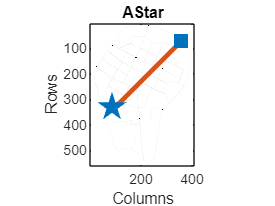

[startPoint, stopPoint] = startStopGenerator(binaryMap);
planner = plannerAStarGrid(costOccMap);
plan(planner,startPoint,stopPoint);
show(planner)

test_map = costMap_normalized*0.99;
test_map(test_map==0) = 1;
testOccMap = occupancyMap(test_map);

[startPoint, stopPoint] = startStopGenerator(binaryMap);
planner = plannerAStarGrid(testOccMap);
path = plan(planner,startPoint,stopPoint);

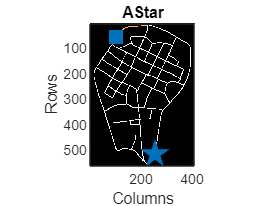

show(planner)

for i=1:1:100
    [startPoint, stopPoint] = startStopGenerator(binaryMap);
    a = length(task_1(map, startPoint, stopPoint))
    if a == 0
        disp("dupa")
    end
end

a = 334

a = 360

a = 449

a = 405

a = 362

a = 514

a = 346

a = 305

a = 247

a = 313

a = 437

a = 334

a = 408

a = 363

a = 490

a = 424

a = 232

a = 358

a = 351

a = 343

a = 372

a = 423

a = 377

a = 341

a = 447

a = 295

a = 511

a = 329

a = 344

a = 436

a = 469

a = 355

a = 385

a = 377

a = 402

a = 422

a = 359

a = 395

a = 408

a = 377

a = 410

a = 427

a = 401

a = 460

a = 333

a = 271

a = 365

a = 350

a = 451

a = 251

a = 441

a = 317

a = 338

a = 342

a = 395

a = 309

a = 284

a = 432

a = 296

a = 319

a = 378

a = 347

a = 362

a = 372

a = 361

a = 294

a = 315

a = 528

a = 277

a = 399

a = 410

a = 386

a = 229

a = 509

a = 524

a = 391

a = 315

a = 264

a = 365

a = 267

a = 364

a = 410

a = 497

a = 493

a = 467

a = 397

a = 385

a = 380

a = 472

a = 282

a = 255

a = 434

a = 337

a = 327

a = 443

a = 397

a = 439

a = 511

a = 276

a = 319